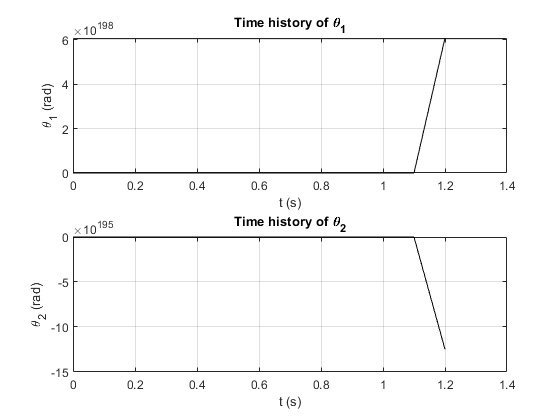

clear
clc
format long

m1=1;
m2=1;
l1=0.01; 
l2=1;
g=9.81;

y0=[0,0,pi/4,0];

h=0.1;
tf=10;

%mit
%f = @(t,y) [y(2); (-g*(2*m1+m2)*sin(y(1))-m2*g*sin(y(1)-2*y(3))-2*sin(y(1)-y(3))*m2*((y(4)^2)*l2+(y(2)^2)*l1*cos(y(1)-y(3))))/(l1*(2*m1+m2-m2*cos(2*y(1)-2*y(3)))); y(4); (2*sin(y(1)-y(3))*((y(2)^2)*l1*(m1+m2)+g*(m1+m2)*cos(y(1))+(y(4)^2)*l2*m2*cos(y(1)-y(3))))/(l2*(2*m1+m2-m2*cos(2*y(1)-2*y(3))))];

%handout
f = @(t,y) [y(2); (-m2*cos(y(1)-y(3))*l1*(y(2)^2)*sin(y(1)-y(3))+m2*cos(y(1)-y(3))*g*sin(y(3))-m2*l2*(y(4)^2)*sin(y(1)-y(3))-(m1+m2)*g*sin(y(1)))/(l1*(m1+m2-m2*(cos(y(1)-y(3)))^2)) ; y(4); (m1+m2)*(l1*(y(2)^2)*sin(y(1)-y(3))+((y(4)^2)*sin(y(1)-y(3))*cos(y(1)-y(3))*m2*l2)/(m1+m2)+cos(y(1)-y(3))*g*sin(y(1))-g*sin(y(3)))/(l2*(m1+m2*(sin(y(1)-y(3)))^2))];

tspan=[0, tf];

[t,y] = explicitEuler(f,tspan,y0,h);

x1 = l1*sin(y(1,:));
y1=-l1*cos(y(1,:));
x2=x1+l2*sin(y(3,:));
y2=y1-l2*cos(y(3,:));

a=figure;
subplot(2,1,1);
plot(t,y(1,:),'k')
grid on
xlabel('t (s)')
ylabel('\theta_1 (rad)')
title('Time history of \theta_1')
subplot(2,1,2);
plot(t,y(3,:),'k')
grid on
xlabel('t (s)')
ylabel('\theta_2 (rad)')
title('Time history of \theta_2')
saveas(a,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q2','Q21.png'))

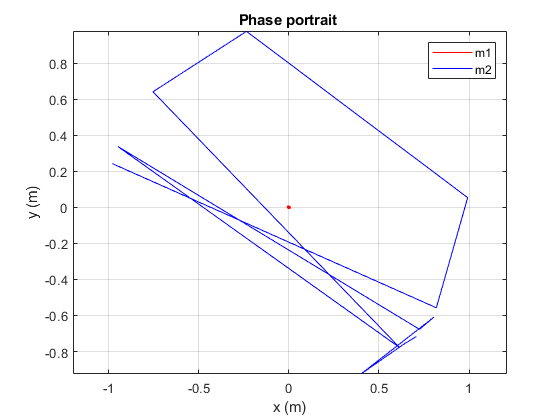


b=figure;
plot(x1,y1,'r')
grid on
axis equal
hold on
plot(x2,y2,'b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait ')
legend('m1','m2')
saveas(b,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q2','Q22.png'))

function [t,y] = explicitEuler(f,tspan,y0,h)
% Explicit Euler 

% Takes a function f, time span, initial condition and number of time step
% as input 

m = length(y0);
t = tspan(1):h:tspan(2); % Uniform grid 
N = length(t); % Number of grid points 
y = zeros(m,N); % Initialise variable representing numerical solution 
y(:,1) = y0; % Initial condition 

% This loop executes explicit Euler 
for i = 1:N-1
    y(:,i+1) = y(:,i) + h*f(t(i),y(:,i));
end
end